clear; close all; clc;
%C_D_0 = .0075;
e = .9;
rho = 1.0834; % Density at a+*lt
r = convlength(250,"ft","m"); % radius of tunr for sink rate requirement
%W_MGTO = 7354.9875; % Maximum Gross Takeoff Weight (N) (DG-1000)
W_MGTO = 700*9.81; % Maximum Gross Takeoff Weight (N) (our aircraft)
b = 20; % wingspan (m)
C_L_max = 2.5; % flapped
%C_L_max = 1.4; % unflapped

W2S_plot_max = 1000;

syms Aspect


% drag polar estimation
% confirm c_f value form DG-1000
S_wet_fuse_DG1000 = 19.4; % wetted area of fuselage (m)
S_wet_wing_DG1000 = 34.5; % wetted area of fuselage (m)
S_wet_DG1000 = S_wet_fuse_DG1000 + S_wet_wing_DG1000; % total wetted area (m)
c_f = .00245;
f_DG1000 = EquivalentParasiteArea(c_f, S_wet_DG1000);
S_DG100 = 17.53;
C_D_0_DG1000 = DragCoefficientZeroLift(f_DG1000, S_DG100);


% now generate C_D_0 as a function of aspect ratio

% compute wetteed area
S = b^2/Aspect; % compute planform area
S_wet_wing = S_wet_wing_DG1000 * S / S_DG100; % find wing wetted area
S_wet = S_wet_fuse_DG1000 + S_wet_wing; % find total wetted area
%get C_D_0
f = EquivalentParasiteArea(c_f, S_wet); % find equivalent prasite area
C_D_0 = DragCoefficientZeroLift(f, S); % get Parasite Drag
%C_D_0 = C_D_0 +.015 % flapped C_D_0 increment
%C_D_0 = C_D_0 +.008 % morphing wing variant (from morphing du-89 paper)

% define the sink rates given in the spec
V_sc_threshold = convvel(250,"ft/min","m/s"); % threshold
V_sc_objective = convvel(175,"ft/min","m/s"); % objective

Aspects = linspace(1,50,100);
C_D_0 = double(subs(C_D_0, Aspect, Aspects));

C_L = C_L_max; % assume that the C_L_max is as close maximising (C_L^(3/2)/C_D) as possilbe

W2S_sink_threshold = W2S_SinkRateCircle(V_sc_threshold, r, C_D_0, C_L, Aspects, e, rho);

g = 9.8100

$$wingLoading\_Realified = \frac{{\mathrm{A\_}}^{2}\,{C_{\mathrm{L\_}}}^{3}\,{V_{\mathrm{sc\_}}}^{2}\,{\mathrm{e\_}}^{2}\,\mathrm{rho\_}\,\pi^{2}\,{\mathrm{root}\left({\mathrm{A\_}}^{4}\,{C_{\mathrm{L\_}}}^{4}\,{V_{\mathrm{sc\_}}}^{4}\,{\mathrm{e\_}}^{4}\,z^{6}\,\pi^{4}+4\,\pi \,\mathrm{A\_}\,C_{D,\mathrm{0\_}}\,{C_{\mathrm{L\_}}}^{6}\,\mathrm{e\_}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}+4\,{\mathrm{A\_}}^{3}\,{C_{D,\mathrm{0\_}}}^{3}\,{C_{\mathrm{L\_}}}^{2}\,{\mathrm{e\_}}^{3}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}\,\pi^{3}+6\,{\mathrm{A\_}}^{2}\,{C_{D,\mathrm{0\_}}}^{2}\,{C_{\mathrm{L\_}}}^{4}\,{\mathrm{e\_}}^{2}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}\,\pi^{2}+{\mathrm{A\_}}^{4}\,{C_{D,\mathrm{0\_}}}^{4}\,{\mathrm{e\_}}^{4}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}\,\pi^{4}+{C_{\mathrm{L\_}}}^{8}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}-4\,\pi \,\mathrm{A\_}\,C_{D,\mathrm{0\_}}\,{C_{\mathrm{L\_}}}^{6}\,\mathrm{e\_}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}-4\,{\mathrm{A\_}}^{3}\,{C_{D,\mathrm{0\_}}}^{3}\,{C_{\mathrm{L\_}}}^{2}\,{\mathrm{e\_}}^{3}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,\pi^{3}-6\,{\mathrm{A\_}}^{2}\,{C_{D,\mathrm{0\_}}}^{2}\,{C_{\mathrm{L\_}}}^{4}\,{\mathrm{e\_}}^{2}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,\pi^{2}-{\mathrm{A\_}}^{4}\,{C_{D,\mathrm{0\_}}}^{4}\,{\mathrm{e\_}}^{4}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,\pi^{4}-{C_{\mathrm{L\_}}}^{8}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2},z,1\right)}^{3}}{2\,{\left({C_{\mathrm{L\_}}}^{2}+\pi \,\mathrm{A\_}\,C_{D,\mathrm{0\_}}\,\mathrm{e\_}\right)}^{2}}$$

W2S_sink_objective = W2S_SinkRateCircle(V_sc_objective, r, C_D_0, C_L, Aspects, e, rho);

g = 9.8100

$$wingLoading\_Realified = \frac{{\mathrm{A\_}}^{2}\,{C_{\mathrm{L\_}}}^{3}\,{V_{\mathrm{sc\_}}}^{2}\,{\mathrm{e\_}}^{2}\,\mathrm{rho\_}\,\pi^{2}\,{\mathrm{root}\left({\mathrm{A\_}}^{4}\,{C_{\mathrm{L\_}}}^{4}\,{V_{\mathrm{sc\_}}}^{4}\,{\mathrm{e\_}}^{4}\,z^{6}\,\pi^{4}+4\,\pi \,\mathrm{A\_}\,C_{D,\mathrm{0\_}}\,{C_{\mathrm{L\_}}}^{6}\,\mathrm{e\_}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}+4\,{\mathrm{A\_}}^{3}\,{C_{D,\mathrm{0\_}}}^{3}\,{C_{\mathrm{L\_}}}^{2}\,{\mathrm{e\_}}^{3}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}\,\pi^{3}+6\,{\mathrm{A\_}}^{2}\,{C_{D,\mathrm{0\_}}}^{2}\,{C_{\mathrm{L\_}}}^{4}\,{\mathrm{e\_}}^{2}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}\,\pi^{2}+{\mathrm{A\_}}^{4}\,{C_{D,\mathrm{0\_}}}^{4}\,{\mathrm{e\_}}^{4}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}\,\pi^{4}+{C_{\mathrm{L\_}}}^{8}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,z^{2}-4\,\pi \,\mathrm{A\_}\,C_{D,\mathrm{0\_}}\,{C_{\mathrm{L\_}}}^{6}\,\mathrm{e\_}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}-4\,{\mathrm{A\_}}^{3}\,{C_{D,\mathrm{0\_}}}^{3}\,{C_{\mathrm{L\_}}}^{2}\,{\mathrm{e\_}}^{3}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,\pi^{3}-6\,{\mathrm{A\_}}^{2}\,{C_{D,\mathrm{0\_}}}^{2}\,{C_{\mathrm{L\_}}}^{4}\,{\mathrm{e\_}}^{2}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,\pi^{2}-{\mathrm{A\_}}^{4}\,{C_{D,\mathrm{0\_}}}^{4}\,{\mathrm{e\_}}^{4}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2}\,\pi^{4}-{C_{\mathrm{L\_}}}^{8}\,{\mathrm{g\_}}^{2}\,{\mathrm{r\_}}^{2},z,1\right)}^{3}}{2\,{\left({C_{\mathrm{L\_}}}^{2}+\pi \,\mathrm{A\_}\,C_{D,\mathrm{0\_}}\,\mathrm{e\_}\right)}^{2}}$$

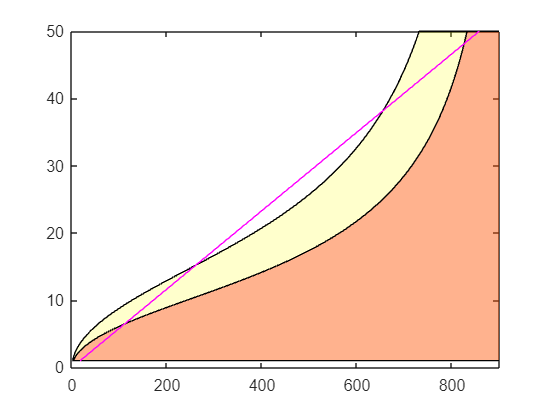


plot(W2S_sink_threshold, Aspects);
ylim([0,50]); xlim([0,1000]);

% plot atainable wing loading line
hold on;
plot(W2S_sink_objective, Aspects);

% plot using fill regions
boundrayEdges_Ycoords = [Aspects, fliplr(Aspects)];
threshold_boundrayEdges_Xcoords = [ones(size(W2S_sink_threshold))*1000, fliplr(W2S_sink_threshold)];
objective_boundrayEdges_Ycoords = [ones(size(W2S_sink_objective))*1000, fliplr(W2S_sink_objective)];

fill(objective_boundrayEdges_Ycoords, boundrayEdges_Ycoords, [1,1,0],"FaceAlpha",.20)
fill(threshold_boundrayEdges_Xcoords, boundrayEdges_Ycoords, [1,0,0],"FaceAlpha",.30)
xlim([0,900]);


% plot aspectratio  wingloanding relationship for b=20
S_possible = b^2 ./ Aspects;
W2S_possible = W_MGTO ./ S_possible;
plot(W2S_possible, Aspects,"m");

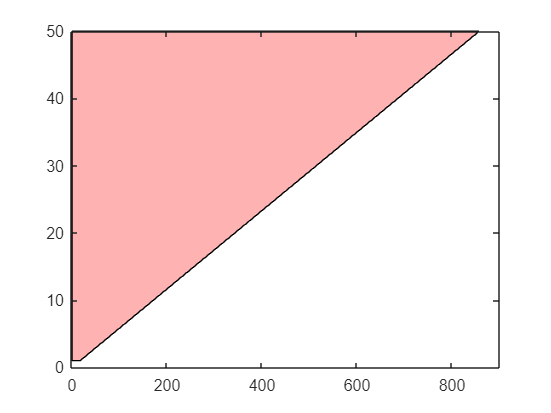


figure;
exclude_Apsect2W2S = [zeros(size(Aspects)), fliplr(W2S_possible)];
fill(exclude_Apsect2W2S, boundrayEdges_Ycoords, [1,0,0],"FaceAlpha",.30);
xlim([0,900]);